%Abhay Nanduri
%AIE-B
%CH.EN.U4AIE21130

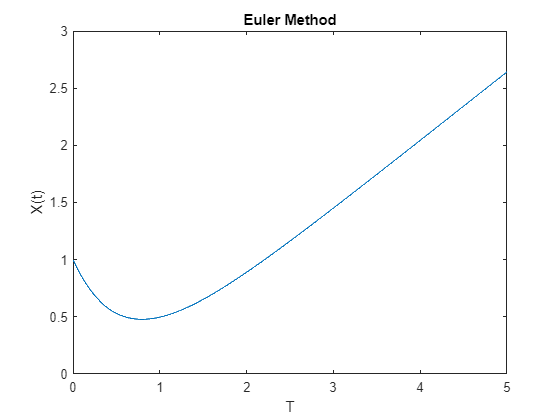

% Program 1(A): Solving the x'=-2x+t ODE by using the
%euler method
clear;
% Coefficients of the equation: ax'=bx+ct
a=3.;
b=-5.;
c=3.;
% Initial and final times
tinit= 0.;
tmax=5.;
% Number of time steps
maxt = 3000;
dt = (tmax-tinit)/maxt;
% Initial condition
x(1)=1.;
t(1)=tinit;
% Time loop
for j=1:maxt
x(j+1)=x(j)+dt*((b*x(j)+c*(j)*dt)/a);
t(j+1)=tinit+j*dt;
end
% Figure
plot(t,x)
title('Euler Method')
xlabel('T')
ylabel('X(t)')

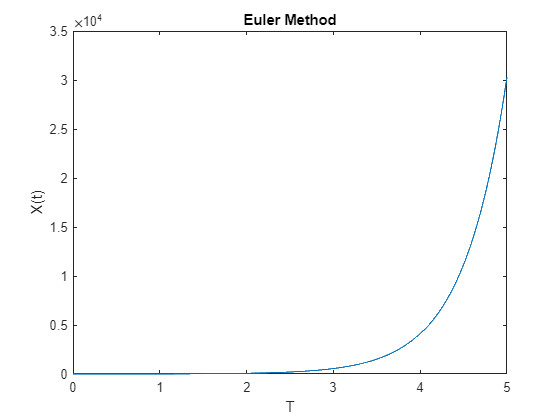

% Program 1(B): Solving the x'=-2x+t ODE by using the
%euler method
clear;
% Coefficients of the equation: ax'=bx+ct
a=5.;
b=10.;
c=8.;
% Initial and final times
tinit= 0.;
tmax=5.;
% Number of time steps
maxt = 3000;
dt = (tmax-tinit)/maxt;
% Initial condition
x(1)=1.;
t(1)=tinit;
% Time loop
for j=1:maxt
x(j+1)=x(j)+dt*((b*x(j)+c*(j)*dt)/a);
t(j+1)=tinit+j*dt;
end
% Figure
plot(t,x)
title('Euler Method')
xlabel('T')
ylabel('X(t)')

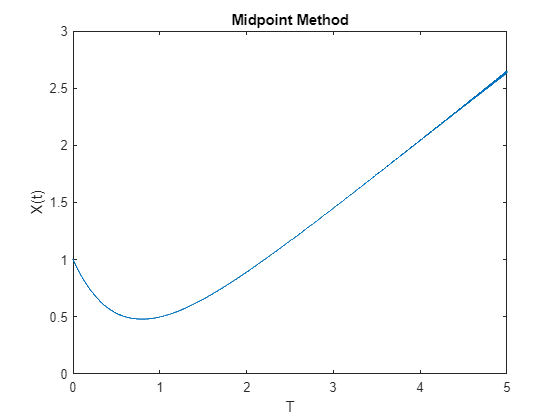

% Program 2 (A): Solving the a x'=b x + c t ODE by using the
%midpoint method
clear;
% Coefficients of equation a x'=b x + c t
a=3.;
b=-5.;
c=3.;
% Initial and Final Times
tinit= 0.;
tmax=5.;
% Number of Time Steps
maxt = 3000;
dt = (tmax-tinit)/maxt;
% Initial Condition
x(2)=1.;
x(1)=1.0-dt*((b*x(2)+c*(2)*dt)/a);
t(2)=tinit;
% Time Loop
for j=2:(maxt+1)
x(j+1)=x(j-1)+2.*dt*((b*x(j)+c*(j)*dt)/a);
t(j+1)=tinit+(j-1)*dt;
end
plot(t,x)
title('Midpoint Method')
xlabel('T')
ylabel('X(t)')

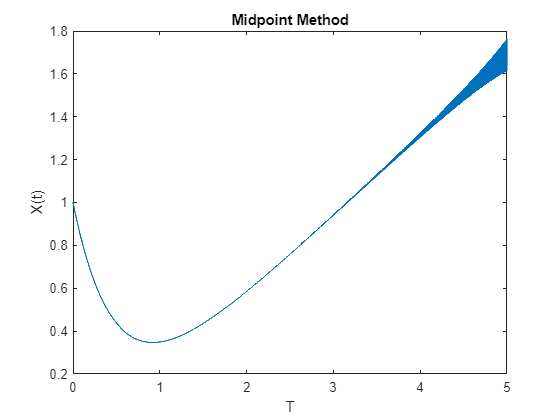

% Program 2(B): Solving the a x'=b x + c t ODE by using the
%midpoint method
clear;
% Coefficients of equation a x'=b x + c t
a=4.;
b=-8.;
c=3.;
% Initial and Final Times
tinit= 0.;
tmax=5.;
% Number of Time Steps
maxt = 3000;
dt = (tmax-tinit)/maxt;
% Initial Condition
x(2)=1.;
x(1)=1.0-dt*((b*x(2)+c*(2)*dt)/a);
t(2)=tinit;
% Time Loop
for j=2:(maxt+1)
x(j+1)=x(j-1)+2.*dt*((b*x(j)+c*(j)*dt)/a);
t(j+1)=tinit+(j-1)*dt;
end
plot(t,x)
title('Midpoint Method')
xlabel('T')
ylabel('X(t)')

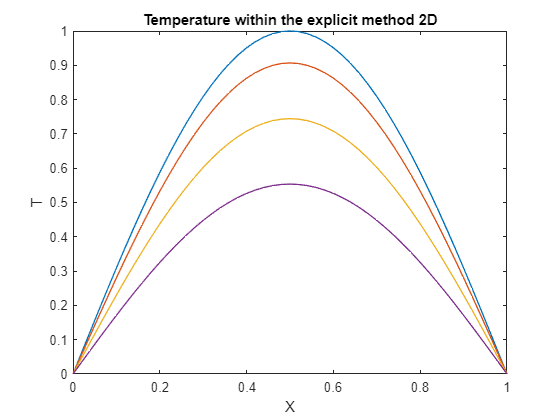

% Program 5(A): Heat Diffusion in one dimensional wire within the
% Explicit Method
clear;
% Parameters to define the heat equation and the range in space and time
L = 1.; % Length of the wire
T =1.; % Final time
% Parameters needed to solve the equation within the explicit method
maxk = 2500; % Number of time steps
dt = T/maxk;
n = 50; % Number of space steps
dx = L/n;
cond = 0.25; % Conductivity
b = 2.*cond*dt/(dx*dx); % Stability parameter (b=<1)
% Initial temperature of the wire: a sinus.
for i = 1:n+1
x(i) =(i-1)*dx;
u(i,1) =sin(pi*x(i));
end
% Temperature at the boundary (T=0)
for k=1:maxk+1
u(1,k) = 0.;
u(n+1,k) = 0.;
time(k) = (k-1)*dt;
end
% Implementation of the explicit method
for k=1:maxk % Time Loop
for i=2:n % Space Loop
    u(i,k+1) =u(i,k) + 0.5*b*(u(i-1,k)+u(i+1,k)-2.*u(i,k));
end
end
% Graphical representation of the temperature at different selected times
figure(1)
plot(x,u(:,1),'-',x,u(:,100),'-',x,u(:,300),'-',x,u(:,600),'-')
title('Temperature within the explicit method 2D')
xlabel('X')
ylabel('T')

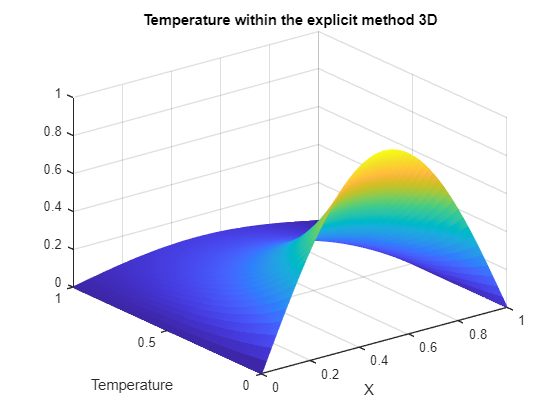

figure(2)
mesh(x,time,u')
title('Temperature within the explicit method 3D')
xlabel('X')
ylabel('Temperature')

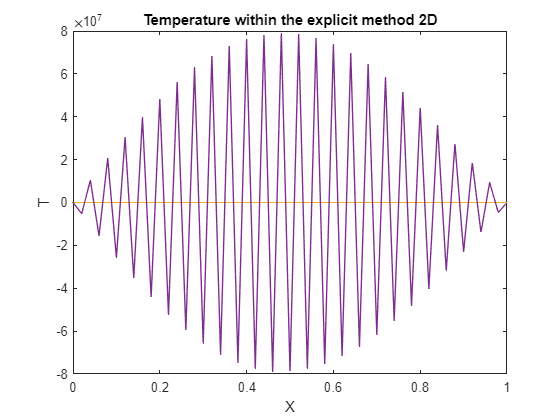

% Program 5(B): Heat Diffusion in one dimensional wire within the
% Explicit Method
clear;
% Parameters to define the heat equation and the range in space and time
L = 1.; % Length of the wire
T =1.; % Final time
% Parameters needed to solve the equation within the explicit method
maxk = 2500; % Number of time steps
dt = T/maxk;
n = 50; % Number of space steps
dx = L/n;
cond = 0.525; % Conductivity
b = 2.*cond*dt/(dx*dx); % Stability parameter (b=<1)
% Initial temperature of the wire: a sinus.
for i = 1:n+1
x(i) =(i-1)*dx;
u(i,1) =sin(pi*x(i));
end
% Temperature at the boundary (T=0)
for k=1:maxk+1
u(1,k) = 0.;
u(n+1,k) = 0.;
time(k) = (k-1)*dt;
end
% Implementation of the explicit method
for k=1:maxk % Time Loop
for i=2:n % Space Loop
    u(i,k+1) =u(i,k) + 0.5*b*(u(i-1,k)+u(i+1,k)-2.*u(i,k));
end
end
% Graphical representation of the temperature at different selected times
figure(1)
plot(x,u(:,1),'-',x,u(:,100),'-',x,u(:,300),'-',x,u(:,600),'-')
title('Temperature within the explicit method 2D')
xlabel('X')
ylabel('T')

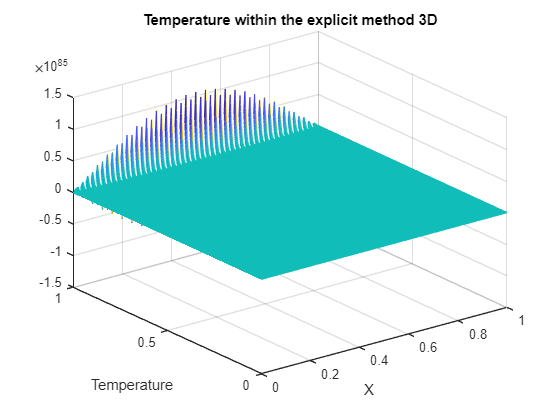

figure(2)
mesh(x,time,u')
title('Temperature within the explicit method 3D')
xlabel('X')
ylabel('Temperature')

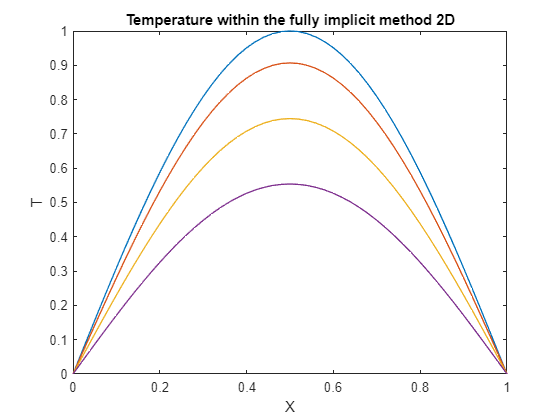

% Program 6(A): Heat Diffusion in one dimensional wire within the Fully
% Implicit Method
clear;
% Parameters to define the heat equation and the range in space and time
L = 1.; % Lenth of the wire
T =1.; % Final time
% Parameters needed to solve the equation within the fully implicit method
maxk = 2500; % Number of time steps
dt = T/maxk;
n = 50.; % Number of space steps
dx = L/n;
cond = 1./4.; % Conductivity
b = cond*dt/(dx*dx); % Parameter of the method
% Initial temperature of the wire: a sinus.
for i = 1:n+1
x(i) =(i-1)*dx;
u(i,1) =sin(pi*x(i));
end
% Temperature at the boundary (T=0)
for k=1:maxk+1
u(1,k) = 0.;
u(n+1,k) = 0.;
time(k) = (k-1)*dt;
end
aa(1:n-2)=-b;
bb(1:n-1)=1.+2.*b;
cc(1:n-2)=-b;
MM=inv(diag(bb,0)+diag(aa,-1)+diag(cc,1));
% Implementation of the implicit method
for k=2:maxk % Time Loop
uu=u(2:n,k-1);
u(2:n,k)=MM*uu;
end
% Graphical representation of the temperature at different selected times
figure(1)
plot(x,u(:,1),'-',x,u(:,100),'-',x,u(:,300),'-',x,u(:,600),'-')
title('Temperature within the fully implicit method 2D')
xlabel('X')
ylabel('T')

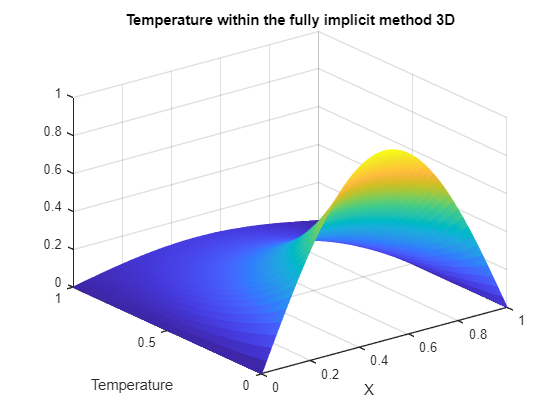

figure(2)
mesh(x,time,u')
title('Temperature within the fully implicit method 3D')
xlabel('X')
ylabel('Temperature')

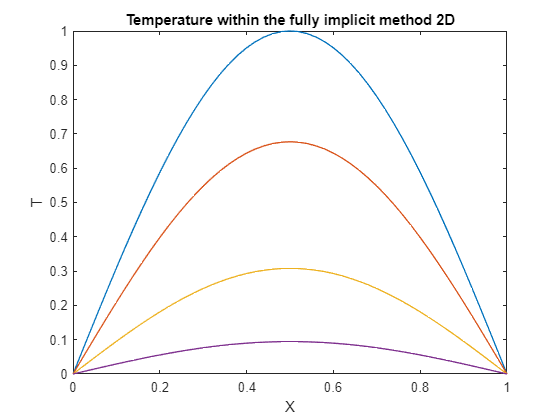

% Program 6(B): Heat Diffusion in one dimensional wire within the Fully
% Implicit Method
clear;
% Parameters to define the heat equation and the range in space and time
L = 1.; % Lenth of the wire
T =1.; % Final time
% Parameters needed to solve the equation within the fully implicit method
maxk = 2500; % Number of time steps
dt = T/maxk;
n = 50.; % Number of space steps
dx = L/n;
cond = 1; % Conductivity
b = cond*dt/(dx*dx); % Parameter of the method
% Initial temperature of the wire: a sinus.
for i = 1:n+1
x(i) =(i-1)*dx;
u(i,1) =sin(pi*x(i));
end
% Temperature at the boundary (T=0)
for k=1:maxk+1
u(1,k) = 0.;
u(n+1,k) = 0.;
time(k) = (k-1)*dt;
end
aa(1:n-2)=-b;
bb(1:n-1)=1.+2.*b;
cc(1:n-2)=-b;
MM=inv(diag(bb,0)+diag(aa,-1)+diag(cc,1));
% Implementation of the implicit method
for k=2:maxk % Time Loop
uu=u(2:n,k-1);
u(2:n,k)=MM*uu;
end
% Graphical representation of the temperature at different selected times
figure(1)
plot(x,u(:,1),'-',x,u(:,100),'-',x,u(:,300),'-',x,u(:,600),'-')
title('Temperature within the fully implicit method 2D')
xlabel('X')
ylabel('T')

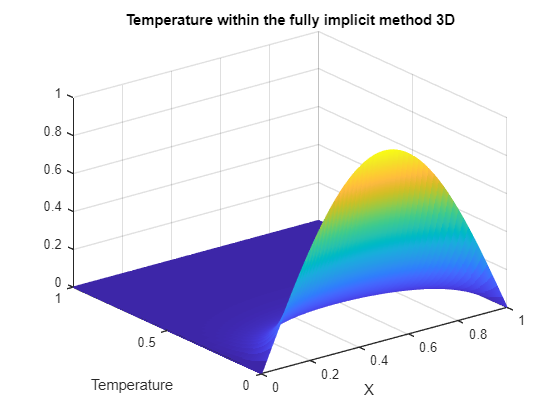

figure(2)
mesh(x,time,u')
title('Temperature within the fully implicit method 3D')
xlabel('X')
ylabel('Temperature')